% AAE666 HW2 EXERCISE1 MATLAB SCRIPT    
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2021-Spring\AAE666\matlab\hw2';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

Amat = @(ye) [0, 1; -(3*ye^2 - 1), -0.1]; 

% ye = -1 
ye = -1;
A = Amat(ye);
[v, lambda] = eig(A);

% ye = 0
y = 0;
A = Amat(ye);
[v, lambda] = eig(A);

% ye = 1
ye = 1;
A = Amat(ye);
[v, lambda] = eig(A);

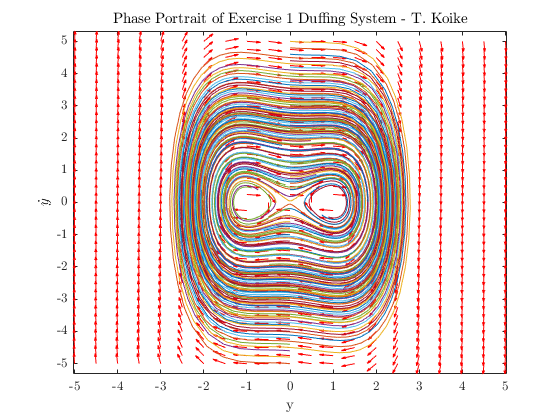

% Phase Portrait
f = @(t,x) [x(2);-0.1*x(2)+x(1)-x(1)^3];
fig = vectfield(f,-5:.5:5,-5:.25:5);
hold on
for y20=-5:0.2:5
  [ts,ys] = ode45(f,[0,10],[0;y20]);
  plot(ys(:,1),ys(:,2))
end
hold off
title('Phase Portrait of Exercise 1 Duffing System - T. Koike')
xlabel('y')
ylabel('$\dot{y}$')
saveas(fig, fullfile(fdir, "ex1-phase-portrait.png"));

function fig = vectfield(func,y1val,y2val,t)
    if nargin==3
      t=0;
    end
    n1=length(y1val);
    n2=length(y2val);
    yp1=zeros(n2,n1);
    yp2=zeros(n2,n1);
    for i=1:n1
      for j=1:n2
        ypv = feval(func,t,[y1val(i);y2val(j)]);
        yp1(j,i) = ypv(1);
        yp2(j,i) = ypv(2);
      end
    end
    len=sqrt(yp1.^2+yp2.^2);
    fig = quiver(y1val,y2val,yp1./len,yp2./len,.6,'r');
    axis tight;
end